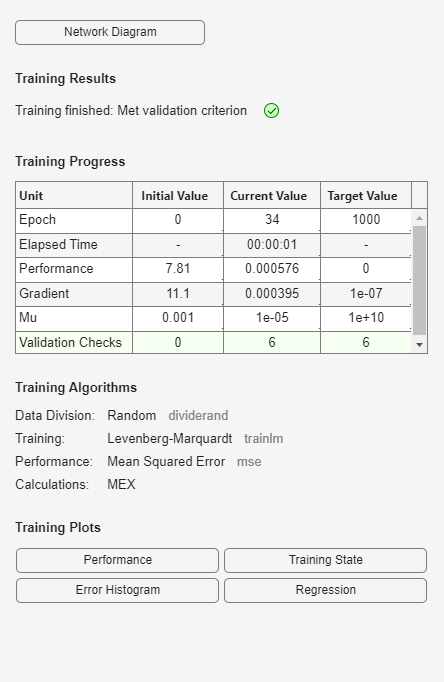

% 训练后分析 (regression)
% 经过训练的网络的性能在一定程度上可以通过基于训练集、验证集和测试集的误差来度量，
% 但更详细地调查网络响应通常是有用的。一种选择是执行网络响应和对应目标之间的回归分析。
% 例程 regression 就是为执行此分析而设计的。
% 以下命令说明如何对经过训练的网络执行回归分析。

x = [-1:.05:1];
t = sin(2*pi*x)+0.1*randn(size(x));
net = feedforwardnet(10);
net = train(net,x,t);

y = net(x);
[r,m,b] = regression(t,y)

r = 0.9625

m = 0.9867

b = -0.0376

% r =    0.9935
% m =    0.9874
% b =   -0.0067
% 将网络输出和对应的目标传递给 regression。它返回三个参数。
% 前两个参数 m 和 b 对应于使目标与网络输出具有最佳线性回归的斜率和 y 截距。
% 如果存在完美拟合（输出完全等于目标），则斜率为 1，y 截距为 0。在此示例中，您可以看到数值非常接近它们。
% regression 返回的第三个变量是输出和目标之间的相关系数（R 值）。
% 它用于衡量目标解释输出变化的程度。如果此数值等于 1，则目标和输出之间就有完美的相关性。
% 在此示例中，该数值非常接近 1，这表明拟合良好。
% 
% 下图显示 regression 提供的图形输出。它是网络输出（用空心圆表示）对目标的图。
% 最佳线性拟合由虚线表示。实线表示完美拟合（输出等于目标）。
% 在此示例中，由于拟合非常好，很难区分最佳线性拟合线和完美拟合线。